# **Activity-Based Assessment-1**

### **Activity-1****: Correlation and Regression line:**

**Q1) Calculate the correlation coefficient between x and y and also find regression line**


$$x=\left\lbrack 1,2,3,4,5,6,7\right\rbrack$$
  


$$y=\left\lbrack 9,8,10,12,11,13,14\right\rbrack$$
 

clear 
x=[1 2 3 4 5 6 7]; 
y=[9 8 10 12 11 13 14]; 
r=corrcoef(x,y)% The non diagonal number is the value of r

r =     1.0000    0.9286
    0.9286    1.0000


% Equation of the lines of regression 
k=polyfit(x,y,1) %y on x

k =     0.9286    7.2857


h=polyfit(y,x,1)

h =     0.9286   -6.2143


a=k(1)

a = 0.9286

b=k(2)

b = 7.2857

fprintf('The regression line y on x is Y=%f*x+%f',a,b)

The regression line y on x is Y=0.928571*x+7.285714

c=h(1)

c = 0.9286

d=h(2)

d = -6.2143

fprintf('The regression line x on y is X=%f*y+%f',c,d)

The regression line x on y is X=0.928571*y+-6.214286

**Q2) Compute the coefficient of correlation and the equation of lines of regression for the data**


$$x=\left\lbrack 1,2,3,4,5,6,7\right\rbrack$$



$$y=\left\lbrack 2,5,3,8,7\right\rbrack$$


clear 
x=[1 2 3 4 5]; 
y=[2 5 3 8 7]; 
r=corrcoef(x,y)% The non diagonal number is the value of r

r =     1.0000    0.8062
    0.8062    1.0000


% Equation of the lines of regression 
k=polyfit(x,y,1) %y on x

k =     1.3000    1.1000


h=polyfit(y,x,1)

h =     0.5000    0.5000


a=k(1)

a = 1.3000

b=k(2)

b = 1.1000

fprintf('The regression line y on x is Y=%f*x+%f',a,b)

The regression line y on x is Y=1.300000*x+1.100000

 c=h(1)

c = 0.5000

d=h(2)

d = 0.5000

fprintf('The regression line x on y is X=%f*y+%f',c,d)

The regression line x on y is X=0.500000*y+0.500000

**Q3) Compute the coefficient of correlation and the equation of lines of regression for the data**


$$x=\left\lbrack 1,3,4,2,5,8,9,10,13,15\right\rbrack$$



$$y=\left\lbrack 8,6,10,8,12,16,16,10,32,32\right\rbrack$$


clear 
x=[1 3 4 2 5 8 9 10 13 15]; 
y=[8 6 10 8 12 16 16 10 32 32]; 
r=corrcoef(x,y) % The non diagonal number is the value of r

r =     1.0000    0.8813
    0.8813    1.0000


% Equation of the lines of regression 
k=polyfit(x,y,1) %y on x

k =     1.7647    2.6471


h=polyfit(y,x,1)

h =     0.4401    0.3985


a=k(1)

a = 1.7647

b=k(2)

b = 2.6471

fprintf('The regression line y on x is Y=%f*x+%f',a,b)

The regression line y on x is Y=1.764706*x+2.647059

c=h(1)

c = 0.4401

d=h(2)

d = 0.3985

fprintf('The regression line x on y is X=%f*y+%f',c,d)

The regression line x on y is X=0.440098*y+0.398533

### Activity-2: Curve fitting using Basic Fitting tool:

**Q1) Fit polynomials upto 5th degree of best fit for the data: **

$x=\left\lbrack 1,2,3,4,5,6,7\right\rbrack$** and **$y=\left\lbrack 9,8,10,11,12,13,14\right\rbrack$** using basic fitting tool.**

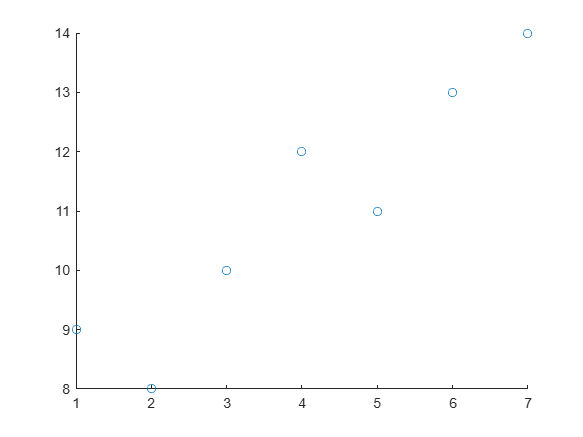

clear
x=[1 2 3 4 5 6 7]; 
y=[9 8 10 12 11 13 14]; 
scatter(x,y)

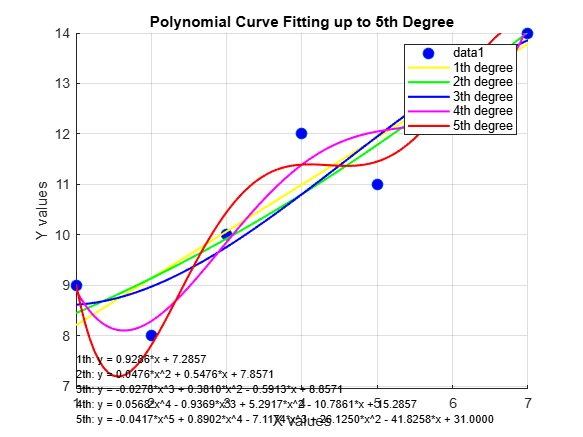

% Given data points
x = [1 2 3 4 5 6 7];
y = [9 8 10 12 11 13 14];

figure;
hold on;
grid on;

% Plot the original data points
plot(x, y, 'o', 'MarkerFaceColor', 'b', 'MarkerSize', 8, 'DisplayName', 'data1');
colors = {'y', 'g', 'b', 'm', 'r'};
all_p = cell(1, 5);

for n = 1:5
    p = polyfit(x, y, n);
    all_p{n} = p;
    x_fit = linspace(min(x), max(x), 100);
    y_fit = polyval(p, x_fit);
    plot(x_fit, y_fit, 'Color', colors{n}, 'LineWidth', 1.5, 'DisplayName', sprintf('%dth degree', n));
end

eqn_array = cell(5, 1);
for n = 1:5
    p = all_p{n};
    eqn = sprintf('%dth: y = ', n);
    for k = 1:length(p)
        coeff = p(k);
        power = length(p) - k;

        if k == 1
            term = sprintf('%.4f', coeff);
        else
            if coeff >= 0
                term = sprintf(' + %.4f', coeff);
            else
                term = sprintf(' - %.4f', abs(coeff));
            end
        end

        if power > 1
            term = [term '*x^' num2str(power)];
        elseif power == 1
            term = [term '*x'];
        end

        eqn = [eqn term];
    end
    eqn_array{n} = eqn;
end
y_min = min(y);
y_range = max(y) - y_min;
line_spacing = y_range * 0.05; 
base_y = y_min - 1.5 * line_spacing; 

for n = 1:5
    y_pos = base_y - (n-1) * line_spacing;
    text(min(x), y_pos, eqn_array{n}, 'FontSize', 8, 'Color', 'k', 'Interpreter', 'none');
end
ylim([base_y - 2*line_spacing, max(y)]);

xlabel('X values');
ylabel('Y values');
title('Polynomial Curve Fitting up to 5th Degree');
legend('Location', 'northeast');
hold off;

Q2) **Fit polynomials upto 5th degree of best fit for the data:**

$x=\left\lbrack 1,2,3,4,5,6\right\rbrack$ and $y=\left\lbrack 2,5,3,8,7,9\right\rbrack$ **using basic fitting tool.**

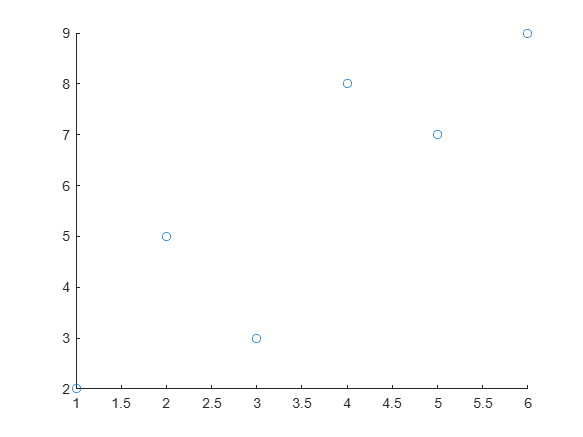

clear
x=[1 2 3 4 5 6]; 
y=[2 5 3 8 7 9]; 
scatter(x,y)

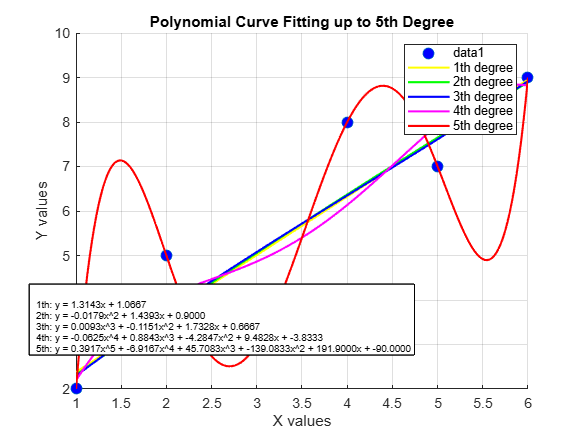

% Given data points
x = [1 2 3 4 5 6];
y = [2 5 3 8 7 9];

figure;
hold on;
grid on;

% Plot the original data points
plot(x, y, 'o', 'MarkerFaceColor', 'b', 'MarkerSize', 8, 'DisplayName', 'data1');
colors = {'y', 'g', 'b', 'm', 'r'};

eqn_str = '';
x_fit = linspace(min(x), max(x), 200); 
for n = 1:5
 p = polyfit(x, y, n);
 y_fit = polyval(p, x_fit);
 plot(x_fit, y_fit, 'Color', colors{n}, 'LineWidth', 1.5, ...
'DisplayName', sprintf('%dth degree', n));
 eqn = 'y = ';
for k = 1:length(p)
 coeff = p(k);
 power = length(p) - k;
if power > 1
 eqn = sprintf('%s%.4fx^%d + ', eqn, coeff, power);
elseif power == 1
 eqn = sprintf('%s%.4fx + ', eqn, coeff);
else
 eqn = sprintf('%s%.4f', eqn, coeff);
end
end
 eqn_str = sprintf('%s\n%dth: %s', eqn_str, n, eqn);
end

dim = [0.05 0.05 0.7 0.3]; % [x y width height]
annotation('textbox', dim, 'String', eqn_str, 'FitBoxToText', 'on', ...
'BackgroundColor', 'white', 'FontSize', 7, 'Interpreter', 'none');

xlabel('X values');
ylabel('Y values');
title('Polynomial Curve Fitting up to 5th Degree');
legend show;
hold off;

Q3) **Fit polynomials upto 5th degree of best fit for the data:**

$x=\left\lbrack 1,3,4,2,5,8,9,10,13,15\right\rbrack$ and $y=\left\lbrack 8,6,10,8,12,16,16,10,32,32\right\rbrack$ **using basic fitting tool.**

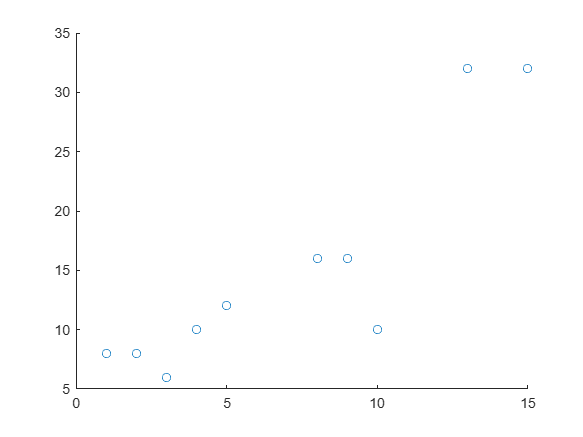

clear 
x=[1 3 4 2 5 8 9 10 13 15]; 
y=[8 6 10 8 12 16 16 10 32 32]; 
scatter(x,y)

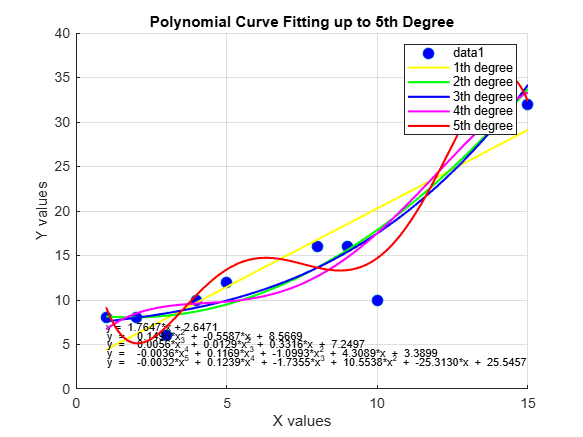

% Given data points
x = [1 3 4 2 5 8 9 10 13 15];
y = [8 6 10 8 12 16 16 10 32 32];

figure;
hold on;
grid on;

% Plot the original data points
plot(x, y, 'o', 'MarkerFaceColor', 'b', 'MarkerSize', 8, 'DisplayName', 'data1');
colors = {'y', 'g', 'b', 'm', 'r'};

for n = 1:5
    p = polyfit(x, y, n);
    x_fit = linspace(min(x), max(x), 100);
    y_fit = polyval(p, x_fit);
    plot(x_fit, y_fit, 'Color', colors{n}, 'LineWidth', 1.5, 'DisplayName', sprintf('%dth degree', n));

    eqn = sprintf('y = ');
    for k = 1:length(p)
        coeff = p(k);
        power = length(p) - k;
        if power > 1
            eqn = sprintf('%s %.4f*x^%d +', eqn, coeff, power);
        elseif power == 1
            eqn = sprintf('%s %.4f*x +', eqn, coeff);
        else
            eqn = sprintf('%s %.4f', eqn, coeff);
        end
    end
    text(x(1), y(1) - n, eqn, 'FontSize', 8);
end

xlabel('X values');
ylabel('Y values');
title('Polynomial Curve Fitting up to 5th Degree');
legend show;
hold off;

### Activity-3

**Obtain the coefficient of correlation, lines of regression and fit curves upto 5th degree polynomial for the data given which represents 10 year cardiac risk vs normal cardiac risk of 124 people working in a factory.**

data=readtable("Data.xlsx")

data = 123x2 table
    Your10_YearRisk    NORMALRISK
    _______________    __________

        38.395            12.38  
        0.9839           1.2861  
        8.0273           4.2933  
        1.1258            1.515  
        14.744           4.2664  
        5.9026           4.9797  
        3.2777            2.851  
        3.3157            1.515  
        15.635           8.4143  
        2.1646           1.7677  
        1.2325           1.3977  
        1.3638           1.2861  
        4.5103           3.8265  
        5.8677           5.2338  
        3.1381           3.8265  
        8.2099           3.8265  


x=data.Your10_YearRisk

x =    38.3952
    0.9839
    8.0273
    1.1258
   14.7440
    5.9026
    3.2777
    3.3157
   15.6351
    2.1646


y=data.NORMALRISK

y =    12.3801
    1.2861
    4.2933
    1.5150
    4.2664
    4.9797
    2.8510
    1.5150
    8.4143
    1.7677


y_on_x=polyfit(x,y,1)

y_on_x =     0.2677    1.8841


x_on_y=polyfit(y,x,1)

x_on_y =     2.3373   -1.9614


A=y_on_x(1)

A = 0.2677

B=y_on_x(2)

B = 1.8841

fprintf("line of regression y on x y=%f*x+%f",A,B)

line of regression y on x y=0.267694*x+1.884095

C=x_on_y(1)

C = 2.3373

D=x_on_y(2)

D = -1.9614

fprintf("line of regression x on y x=%f*y+%f",C,D)

line of regression x on y x=2.337261*y+-1.961400

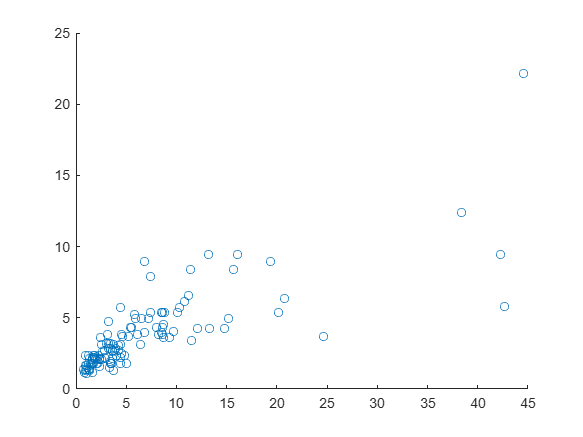

scatter(x,y)

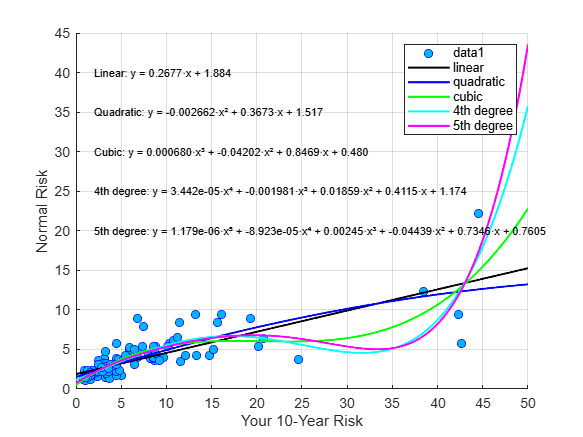

figure;
hold on;
grid on;

scatter(x, y, 'o', 'MarkerFaceColor', [0,0.7,1], 'MarkerEdgeColor', 'b', 'DisplayName', 'data1');
colors = {'k', 'b', 'g', 'c', 'm'};
labels = {'linear', 'quadratic', 'cubic', '4th degree', '5th degree'};

x_smooth = linspace(0, 50, 1000); 
all_p = cell(1, 5);
text_y = 40;
text_x = 2; 

for n = 1:5
    p = polyfit(x, y, n);
    all_p{n} = p;
    y_poly_smooth = polyval(p, x_smooth);
    plot(x_smooth, y_poly_smooth, 'Color', colors{n}, 'LineWidth', 1.5, 'DisplayName', labels{n});
    text_y = text_y - 5;
end

linear_eq = sprintf('Linear: y = %.4f·x + %.3f', all_p{1}(1), all_p{1}(2));
quad_eq = sprintf('Quadratic: y = %.6f·x² + %.4f·x + %.3f', all_p{2}(1), all_p{2}(2), all_p{2}(3));
cubic_eq = sprintf('Cubic: y = %.6f·x³ + %.5f·x² + %.4f·x + %.3f', all_p{3}(1), all_p{3}(2), all_p{3}(3), all_p{3}(4));
fourth_eq = sprintf('4th degree: y = %.3e·x⁴ + %.6f·x³ + %.5f·x² + %.4f·x + %.3f', all_p{4}(1), all_p{4}(2), all_p{4}(3), all_p{4}(4), all_p{4}(5));
fifth_eq = sprintf('5th degree: y = %.3e·x⁵ + %.3e·x⁴ + %.5f·x³ + %.5f·x² + %.4f·x + %.4f', ...
    all_p{5}(1), all_p{5}(2), all_p{5}(3), all_p{5}(4), all_p{5}(5), all_p{5}(6));

text(text_x, 40, linear_eq, 'FontSize', 7.9, 'Interpreter', 'tex');
text(text_x, 35, quad_eq, 'FontSize', 7.9, 'Interpreter', 'tex');
text(text_x, 30, cubic_eq, 'FontSize', 7.9, 'Interpreter', 'tex');
text(text_x, 25, fourth_eq, 'FontSize', 7.9, 'Interpreter', 'tex');
text(text_x, 20, fifth_eq, 'FontSize', 7.9, 'Interpreter', 'tex');

axis([0 50 0 45]);

legend('Location', 'northeast');
xlabel('Your 10-Year Risk');
ylabel('Normal Risk');
set(gca, 'FontSize', 10);
hold off;